Problemset 2: Sea level variability in the Pacific Due Nov 3, 2020.

Tyler Barbero

SIO175

clear;clc;close

**Problem 1 and 2**

load('ALT_Pacific.mat');ALTreadme

ALTreadme = 'sla: sea level anomaly (m), t: datenum time, lon,lat'

load('TGdata.mat');TGreadme

TGreadme = 't: time, sl:sea level (m) Honolulu, San Diego, Mera'

**Problem 3**

**Fit a linear trend, mean and seasonal cycle from each ALT and TG time series using regress.m**

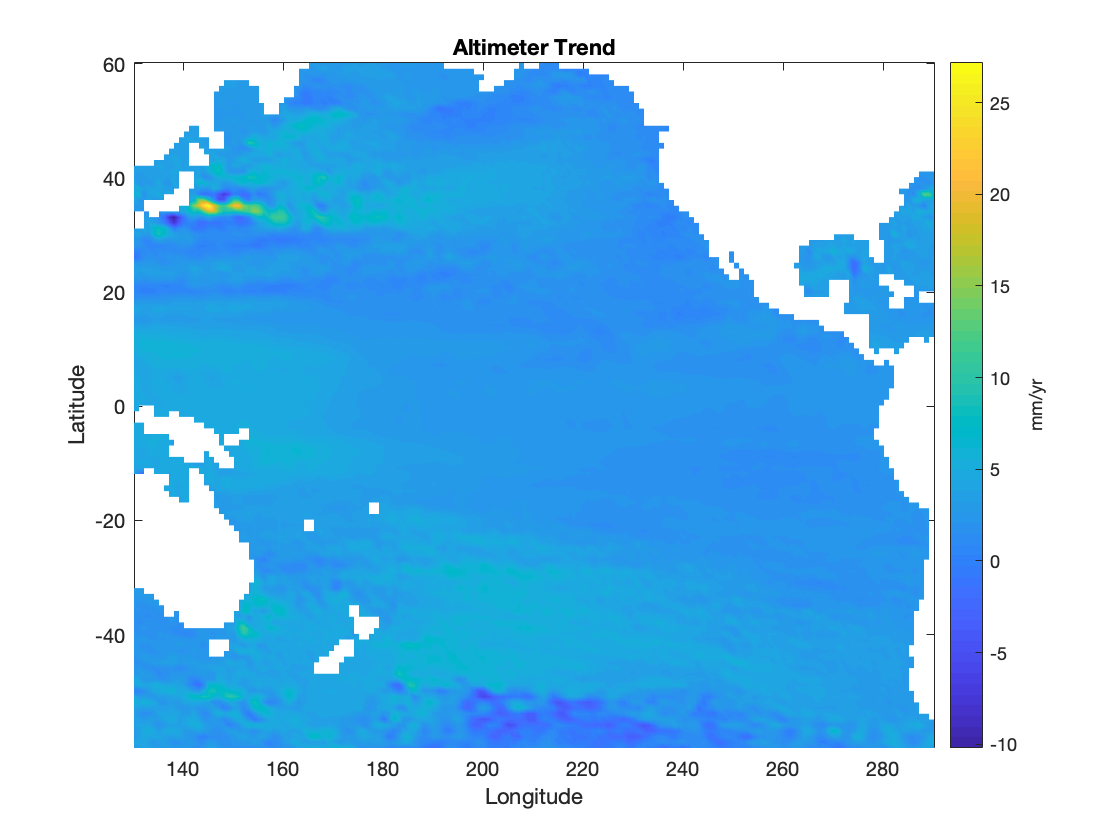

% ALT 
ALT_sl_trend = NaN(numel(ALT.lat),numel(ALT.lon));
arg = 2*pi*ALT.t/365.25;
ALT_x = [ALT.t-nanmean(ALT.t) ones(numel(ALT.t),1) cos(arg) sin(arg) cos(2*arg) sin(2*arg)];
% not doing anything with the mean here...
% b1 = linear trend; b2 = mean offset; b3,4,5,6 = seasonal cycle
ALT_sl = NaN(311,121,161);
ALT_b = NaN(6,121,161);
seas_std = NaN(121,161);

for i=1:121
    for j=1:161
        sl = squeeze(ALT.sl(:,i,j));
        if ~isnan(mean(sl))
            b=regress(sl,ALT_x);
            ALT_sl_trend(i,j) = b(1);
            seas_std(i,j) = (1/sqrt(2))*sqrt(b(3)^2+b(4)^2+b(5)^2+b(6)^2);
        end
        % store b and sl data
        ALT_b(:,i,j) = b;
        ALT_sl(:,i,j) = sl;
    end
end
ALT_sl_trend = ALT_sl_trend*365.25*1000; % convert from m/dy to mm/yr
clearvars sl j1 j2 i j bint b 

% plots
figure(1)
pcolor(ALT.lon,ALT.lat,ALT_sl_trend)
shading interp
h = colorbar;h.Label.String = 'mm/yr';
xlabel('Longitude');ylabel('Latitude')
% caxis([0,15])
title('Altimeter Trend')

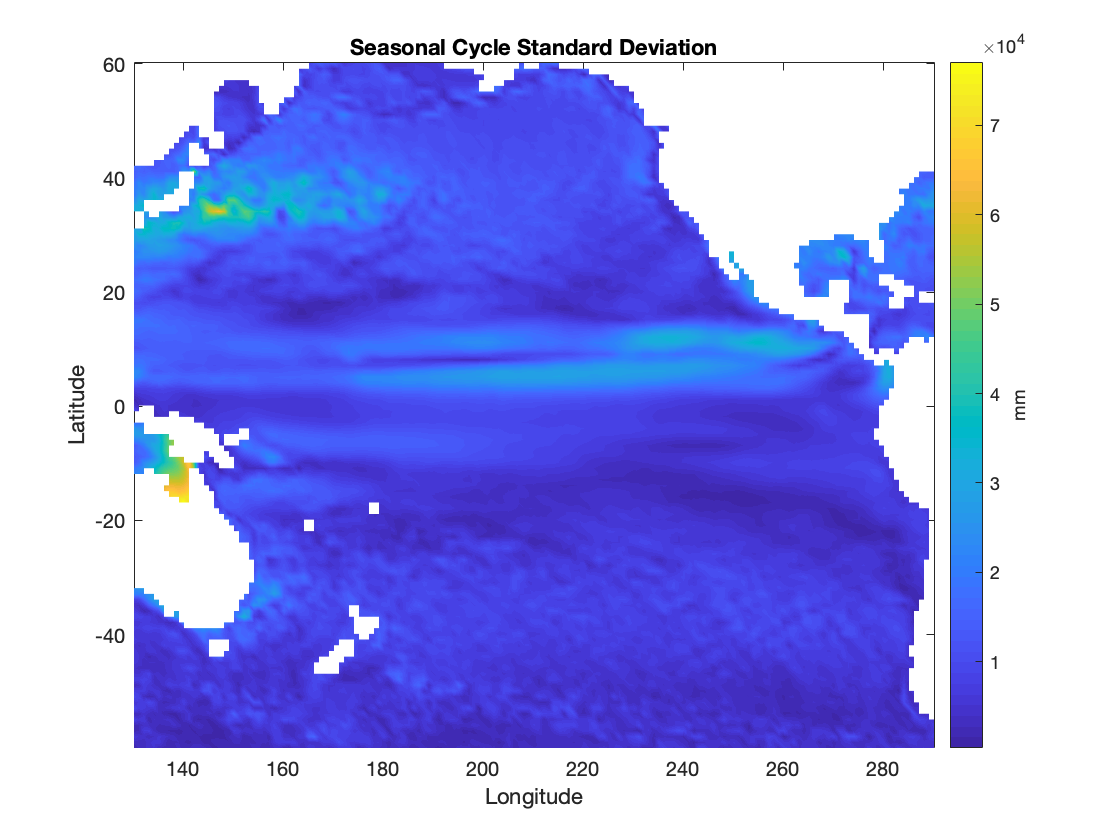

%%
figure(2)
seas_std = seas_std*365.25*1000;
pcolor(ALT.lon,ALT.lat,seas_std)

shading interp
h = colorbar;h.Label.String = 'mm';
xlabel('Longitude');ylabel('Latitude')
set(gca,'ydir','normal')
title('Seasonal Cycle Standard Deviation')


% TG - Fit linear trend, mean, and seasonal cycle 
% define variables
arg = 2*pi*TG.t/365.25;
TG_x = [TG.t-nanmean(TG.t) ones(numel(TG.t),1) cos(arg) sin(arg) cos(2*arg) sin(2*arg)];
TG_b = NaN(6,3);
for i=1:3
    TG_b(:,i) = regress(TG.sl(:,i),TG_x);
end

**Problem 4**

Form sea level anomalies by removing the trend, mean, and seasonal cycle from each ALT and TG time series.

% TG anomaly
TG_anom = TG.sl - TG_x*TG_b;
% ALT anomaly
ALT_anom = NaN(311,121,161);
for i=1:121
    for j=1:161
        ALT_anom(:,i,j) = ALT.sl(:,i,j) - ALT_x * ALT_b(:,i,j);
    end
end

**Problem 5 **				

For each TG station, compute the correlation with every ocean grid point in the ALT array*. *Plot a map of the correlation coefficients. 

End result: a 121x161 array of correlation coefficients

[A,p] = corrcoef(x(:,i),y(:,i)); 

A returns the correlation coefficients in a 2x2 array between xx xy yx yy data. Get A(1,2).

p returns the probability that you would exceed/or be below a value? Each p-value is the probability of getting a correlation as large as the observed value by random chance, when the true correlation is zero.  If P(i,j) is small, say less than 0.05, then the correlation R(i,j) is significant.

coefff = NaN(121,161,3);

for i=1:3
    sl = TG_anom(:,i); % get anomaly
    for j=1:121
        for k=1:161
            A = corrcoef(sl,ALT_anom(:,j,k));
            coefff(j,k,i) = A(1,2);
        end
    end
end

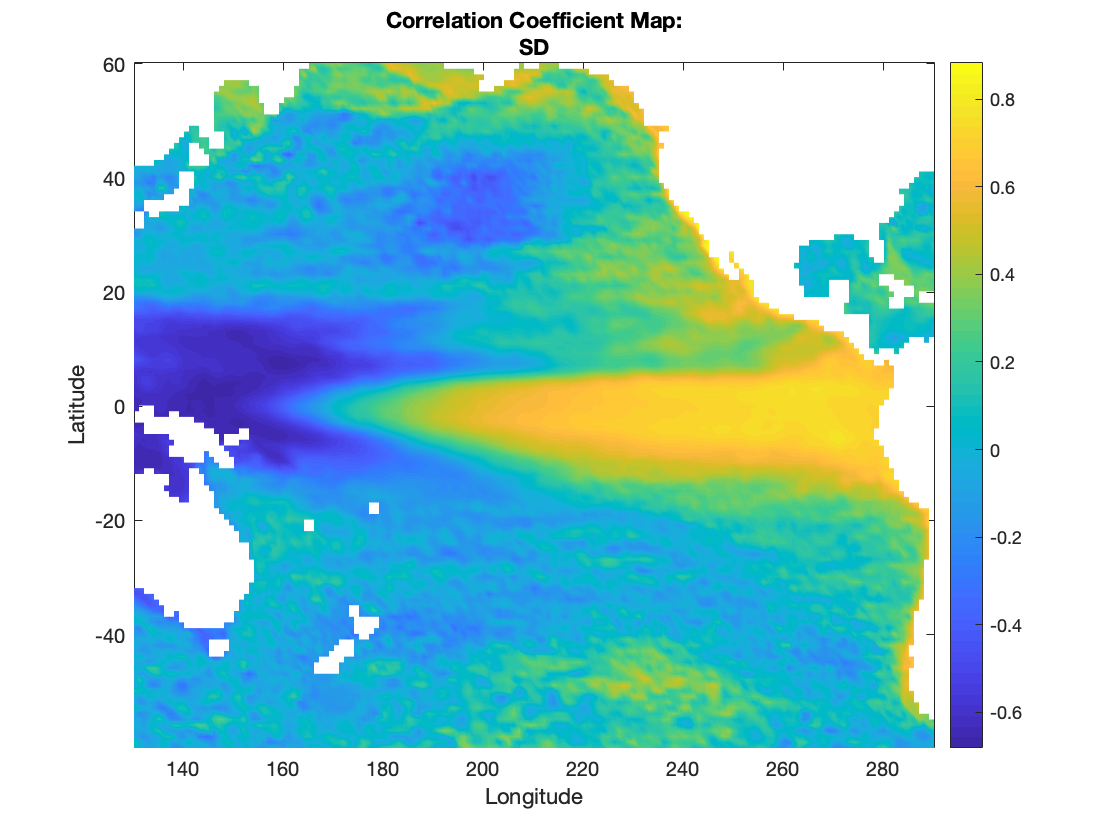

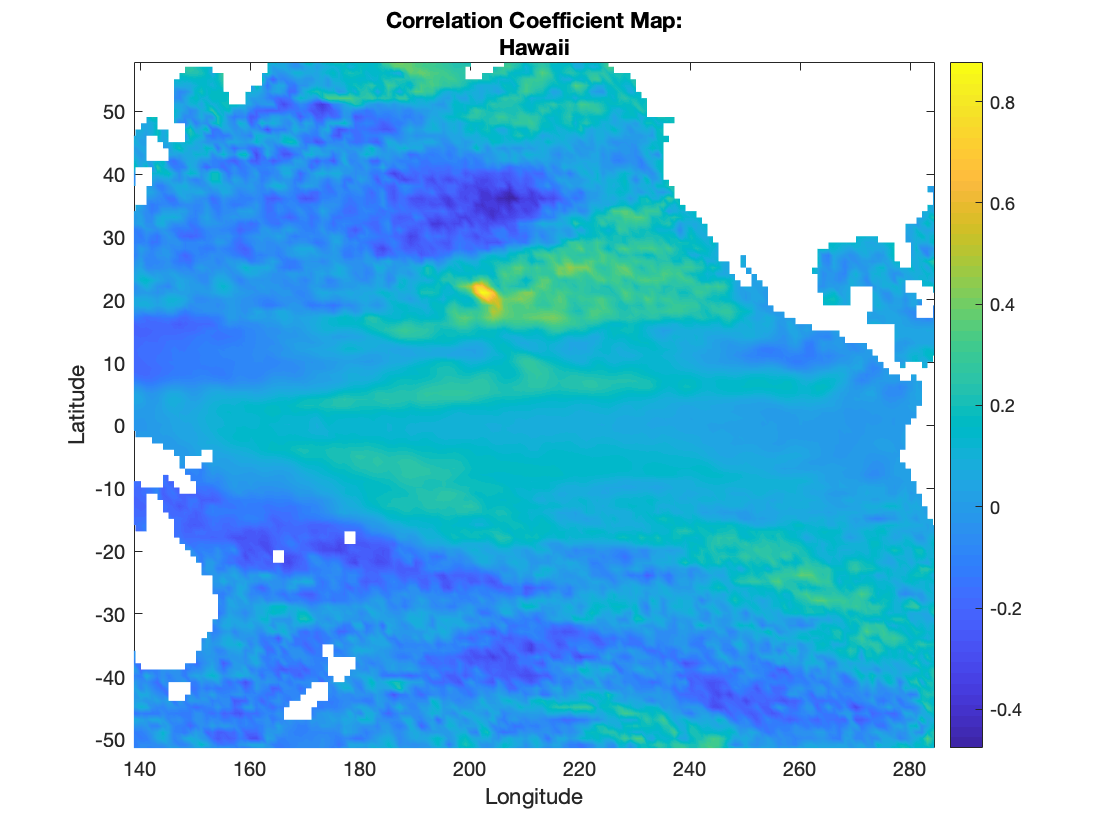

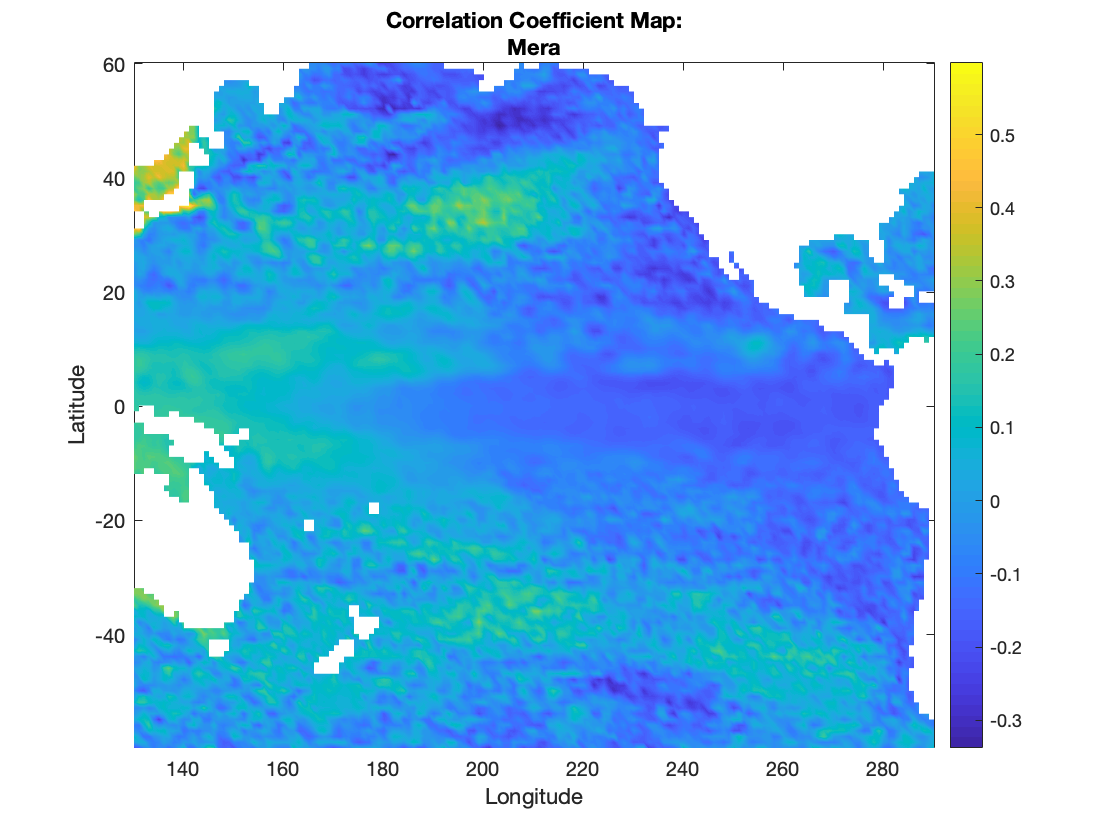

places = ["Hawaii", "SD", "Mera"];
clf
% plots
for i=1:3
    figure(i);pcolor(ALT.lon,ALT.lat,coefff(:,:,i))
    shading interp
    c = colorbar;
    c.Label.String 
    title(['Correlation Coefficient Map:' places(i)])
    xlabel('Longitude')
    ylabel('Latitude')
end

**Problem 6 -- skip**

**Problem 7 **					

For each TG station, compute the regression (ALT = *b ** TG ) with every ocean grid point in the ALT array*. *Plot a map of the regression coefficients. 

b_coeff = NaN(121,161,3);
for i=1:3
    for j=1:121
        for k=1:161
            ALTslanom = squeeze(ALT_anom(:,j,k));
            TGslanom = TG_anom(:,i);
            if ~isnan(mean(TGslanom)) && ~isnan(mean(ALTslanom))
                b = regress(TGslanom,ALTslanom); % every TG site w/ ALT grid
                b_coeff(j,k,i) = b;
            end
        end
    end
end

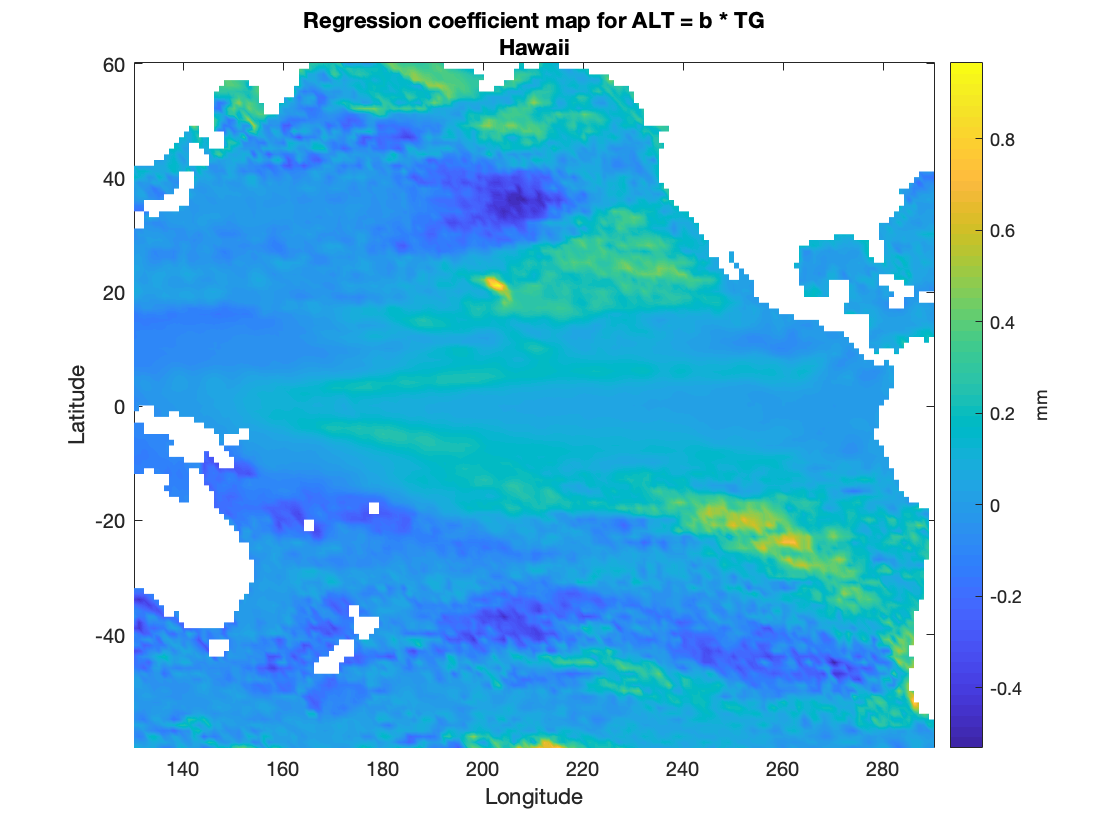

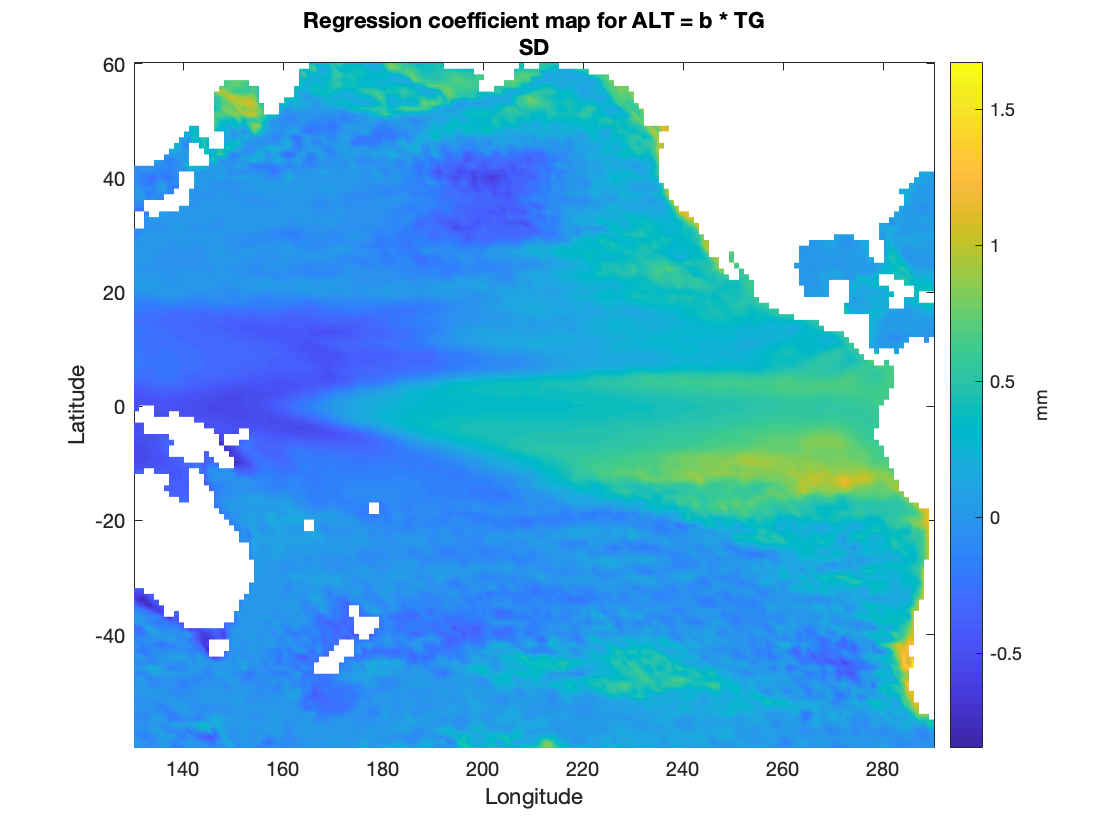

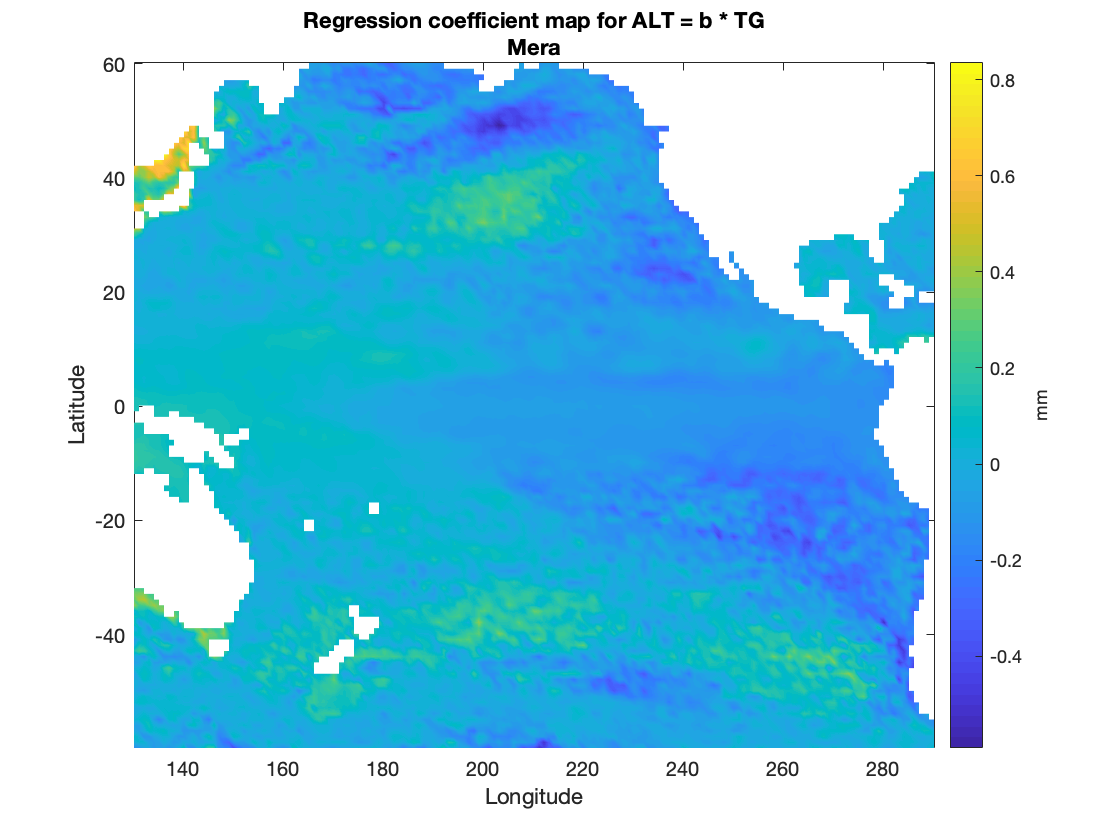

places = ["Hawaii", "SD", "Mera"];
for i=1:3;
    figure(i)
    pcolor(ALT.lon,ALT.lat,b_coeff(:,:,i))
    c = colorbar;
%     caxis([-1 1])
    shading interp
    xlabel('Longitude')
    ylabel('Latitude')
    title(['Regression coefficient map for ALT = b * TG' places(i)])
end

**Problem 8 **

8) Describe dominant patterns in the correlation and regression maps. 

Looking at 5, we see high correlation of SD's TG SL with the east equatorial waters (equatorial cold tongue) from the Altimeter SL data as well as along the coast of the Eastern Pacific. This means that SD sea level is well representative of these same regions. Looking at 7, doing ALT = b * TG, we are essentially fitting one form of SL data to the other, and b is the regression coefficient, which is the best fit between the data (I think). We also see a high regression coefficient (so... high correlation?) at the same area as 5.

Comparing the correlation and regression coefficient maps for Hawaii, we see that sea level is mildly correlated around the equator (not quite on the equator as the correlation values are pretty much blue-green ~ 0 correlation) , the north east pacific area and even a bit more correlated in the south east pacific off the coast of South America. Towards the West pacfic, we see very little correlation of sea level. 

***It is a bit hard to explain where exactly I am currently looking at and trying to describe in text.***

Now looking at Mera, comparing TG sea level data with the Altimter sea level data, we see higher correlation on with grid points located on the Western pacific and branching out towards the north pacific and the south pacific  [Kind of like a sideways U] where we also see little correlation with the east equatorial waters.

***100% - great job!***